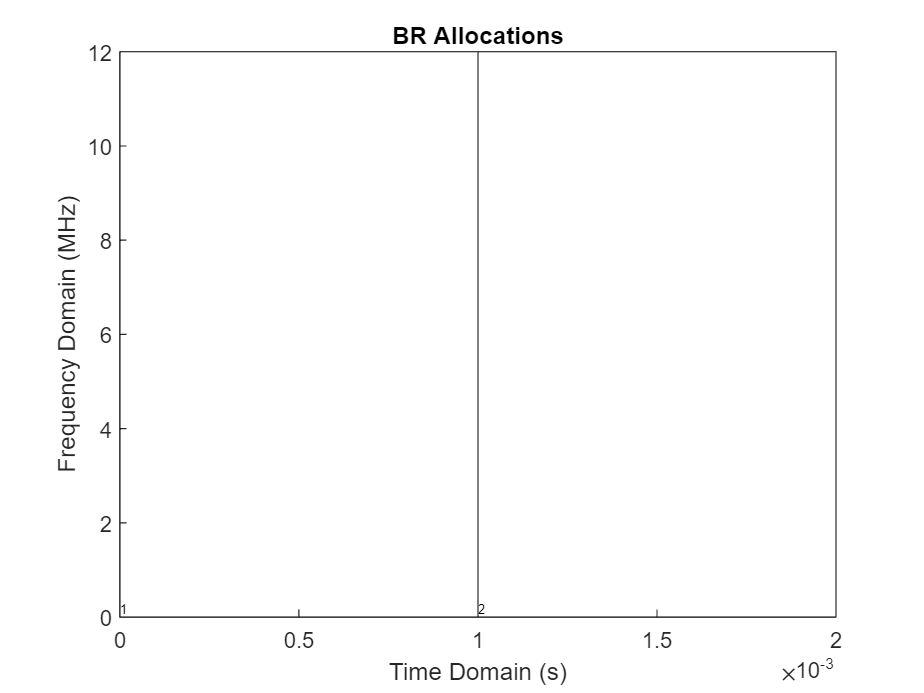

output_container_name = "Output";
output_folder_info = dir(output_container_name);
valid_choice_lambda = @(x) {~strcmp(x.name,".") && ~strcmp(x.name,"..") && x.isdir};
what = cell2mat(arrayfun(valid_choice_lambda, output_folder_info));
output_folder_choices = arrayfun(@(x) {x.name}, output_folder_info(what));
output_folder_choices = string(output_folder_choices);
output_folder = output_folder_choices(1);

experiment_id = "1";



% errors_timetable = parse_errors_timetable(output_container_name, output_folder, experiment_id);
br_topology = parse_br_topology_struct(output_container_name, output_folder, experiment_id);
br_id_timetable = parse_br_id_timetable(output_container_name, output_folder, experiment_id);
% lv_summary = parse_logical_vehicles_summary_struct(output_container_name, output_folder, experiment_id);

br_topology.axes = gca();
br_graph_init_args = namedargs2cell(br_topology);
BRGRaphStruct = BRGraphInit(br_graph_init_args{:});

% BRGraphStruct = BRGraphUpdate("BRGraphStruct", BRGRaphStruct, "BRid", br_id_timetable{1, :}, "pv_to_lv_mapping", lv_summary.pv_to_lv_mapping);




function errors_timetable = parse_errors_timetable(output_container_name, output_folder, experiment_id)
    to_sec = @(s) seconds(sscanf(s,"%f sec"));
    errors_file_name = sprintf("%s/%s/errors-%s.csv", output_container_name, output_folder, experiment_id);
    errors_table = readtable(errors_file_name, "TextType", 'string');
    errors_table_row_times = arrayfun(to_sec, errors_table.Time);
    errors_table.Time = [];
    errors_timetable = table2timetable(errors_table, 'rowTimes', errors_table_row_times);
end

function br_topology = parse_br_topology_struct(output_container_name, output_folder, experiment_id)
    br_topology_file_name = sprintf("%s/%s/br-topology-%s.xml", output_container_name, output_folder, experiment_id);
    br_topology = readstruct(br_topology_file_name);
end

function br_id_timetable = parse_br_id_timetable(output_container_name, output_folder, experiment_id)
    to_sec = @(s) seconds(sscanf(s,"%f sec"));
    br_id_timetable_file_name = sprintf("%s/%s/brid-%s.csv", output_container_name, output_folder, experiment_id);
    br_id_table = readtable(br_id_timetable_file_name, "TextType", 'string', 'ReadVariableNames', 1, 'VariableNamingRule','preserve');
    br_id_table_row_times = arrayfun(to_sec, br_id_table.Time);
    br_id_table.Time = [];
    br_id_timetable = table2timetable(br_id_table, 'rowTimes', br_id_table_row_times);
end

function logical_vehicles_summary = parse_logical_vehicles_summary_struct(output_container_name, output_folder, experiment_id)
    logical_vehicles_summary_file_name = sprintf("%s/%s/lv-summary-%s.xml", output_container_name, output_folder, experiment_id);
    logical_vehicles_summary = readstruct(logical_vehicles_summary_file_name);
end